##                                                                      Robótica - Lista 5

import RoboticaBiblioteca.*

Questão 7

|  link  |  a  | alpha |   d   |  theta           |

| 0 - 1 |  0  |    90   | d0   |    0               |  R

| 1 - 2 | a2 |    90   | 0     | theta2* + 90 |  R

| 2 - 3 |  0  |     0    | d3* |     0               |  P

syms theta1 theta2 theta3;
A01 = denavit(0, 8.8, 0, 0);
A12 = denavit(theta1, 13.5, 0, 90);
A23 = denavit(theta2 + 90, 0, 17, 0);
A34 = denavit(theta3 - 90, 0, 15, 0);
A = A01 * A12 * A23 * A34

$$A = \left(\begin{array}{cccc} \cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{3}-90\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\cos\left(\theta_{1}\right) & -\cos\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\cos\left(\theta_{1}\right)-\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{2}+90\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & 17\,\cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{1}\right)+15\,\cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{3}-90\right)\,\cos\left(\theta_{1}\right)-15\,\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & 17\,\cos\left(\theta_{2}+90\right)\,\sin\left(\theta_{1}\right)+15\,\cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{1}\right)-15\,\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)+\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{2}+90\right) & \cos\left(\theta_{2}+90\right)\,\cos\left(\theta_{3}-90\right)-\sin\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right) & 0 & 17\,\sin\left(\theta_{2}+90\right)+15\,\cos\left(\theta_{2}+90\right)\,\sin\left(\theta_{3}-90\right)+15\,\cos\left(\theta_{3}-90\right)\,\sin\left(\theta_{2}+90\right)+\frac{223}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**MOTOMAN MH5F**

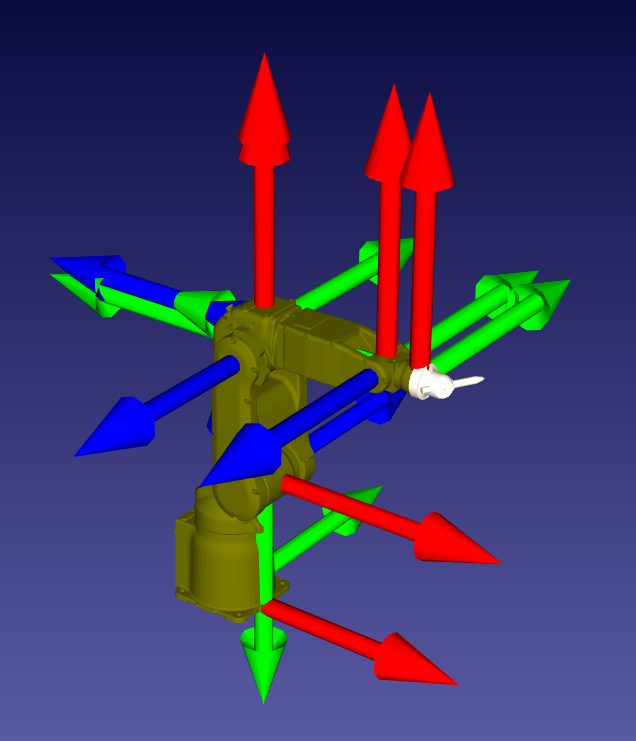

|  link  |   a   | alpha  |    d    |      theta      |

| 0 - 1 |  88  |    -90   |  330  |    theta1*     |  R

| 1 - 2 | 310 | +-180  |    0    | theta2* - 90 |  R

| 2 - 3 |  40  |   -90    |    0    |    theta3*     |  R

| 3 - 4 |   0   |  +90    | -305  |    theta4*     |  R

| 4 - 5 |   0   |   -90    |    0    |    theta5*     |  R

| 5 - 6 |   0   |     0     |  -80   |    theta6*     |  R

% denavit(theta, d, a, alpha) com todos os thetas zerados
A01 = denavit(0,330,88,-90);
A12 = denavit(0-90,0,310,180);
A23 = denavit(0,0,40,-90);
A34 = denavit(0,-305,0,+90);
A45 = denavit(0,0,0,-90);
A56 = denavit(0,-80,0,0);

A06 = A01*A12*A23*A34*A45*A56

A06 =      0     0    -1   473
     0     1     0     0
     1     0     0   680
     0     0     0     1


|  link  |   a   | alpha  |    d    |   theta   |

| 0 - 1 |    0   |    90   |   70   |  theta1* |  R

| 1 - 2 | -210 |     0    |    0    |  theta2* |  R

| 2 - 3 | -200 |     0    |    0    |  theta3* |  R

| 3 - 4 |    0   |  +90   |   50   |  theta4*  |  R

| 4 - 5 |    0   |   -90   |   50   |  theta5*  |  R

| 5 - 6 |    0   |     0    |   40   |  theta6*  |  R

% denavit(theta, d, a, alpha) com theta2 igual a -90 e o resto zero
A01 = denavit(0,70,0,+90);
A12 = denavit(-90,0,-210,0); 
A23 = denavit(0,0,-200,0);
A34 = denavit(0,50,0,-90);
A45 = denavit(0,-50,0,+90);
A56 = denavit(0,40,0,0);

A06 = A01*A12*A23*A34*A45*A56

A06 =      0     1     0   -50
     0     0    -1   -90
    -1     0     0   480
     0     0     0     1


% denavit(theta, d, a, alpha) ABB 1600 145
A01 = denavit(0,486.5,150,-90)

A01 =     1.0000         0         0  150.0000
         0         0    1.0000         0
         0   -1.0000         0  486.5000
         0         0         0    1.0000


A12 = denavit(0-90,0,700,0)

A12 =      0     1     0     0
    -1     0     0  -700
     0     0     1     0
     0     0     0     1


A23 = denavit(0,0,0,-90)

A23 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


A34 = denavit(0,600,0,90)

A34 =      1     0     0     0
     0     0    -1     0
     0     1     0   600
     0     0     0     1


A45 = denavit(0,0,0,-90)

A45 =      1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1


A56 = denavit(0+180,65,0,0)

A56 =     -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1


A06 = A01*A12*A23*A34*A45*A56

A06 = 	1.0e+03 *

         0         0    0.0010    0.8150
         0    0.0010         0         0
   -0.0010         0         0    1.1865
         0         0         0    0.0010
